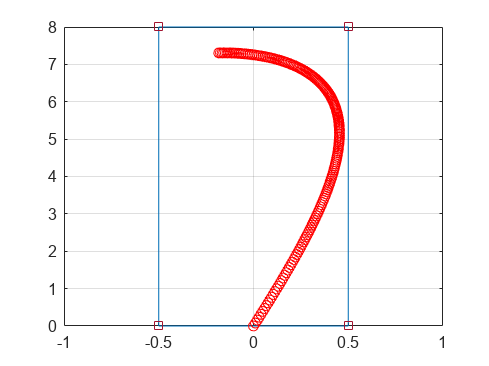

clear
clc
tspan = [0 10];
v0 = 1.6;
n = 200;
y0 = -0.0;
theta = pi/25;

[y,vy,ty] = yEuler(@yOde,tspan,y0,v0,n,theta);
[x,vx,tx] = xEuler(@xOde,tspan,v0,n,theta);
[d1,d2] = drawField();


[x1,vx1,y1,vy1] = calcStop(x,vx,y,vy,n+1);


% plot(y,x,'o b',d1,d2,'s',y1,x1,'x r')
plot(d1,d2,'s',y1,x1,'o r')
grid on
hold off

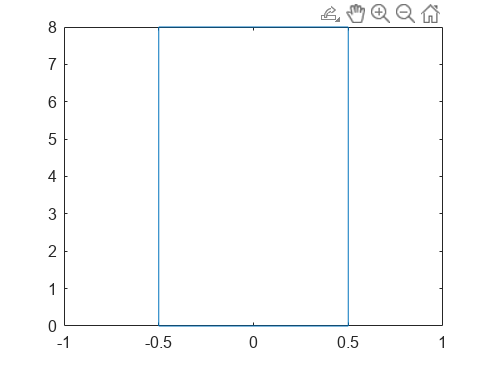

animation(x1,y1)


diff = y(length(y))-y(1)

diff = -0.2721